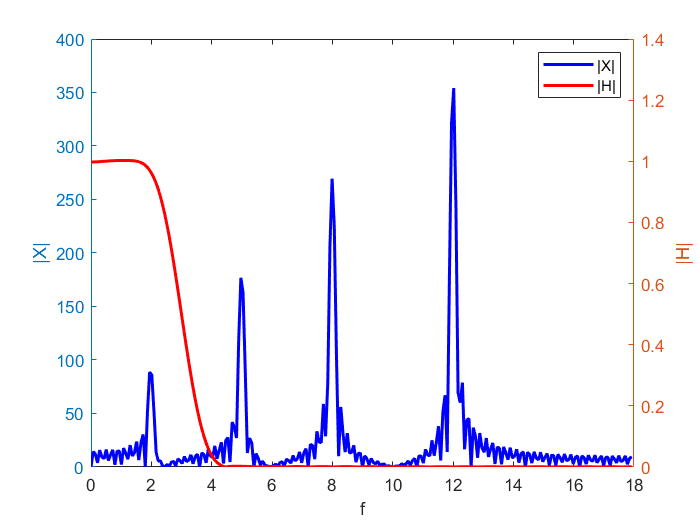

A1 = 1; f1 = 2; 
A2 = 2; f2 = 5;
A3 = 3; f3 = 8;
A4 = 4; f4 = 12;

fs = 36; ts = 1/fs;

t = 0:ts:5;

x1 = A1*sin(2*pi*f1*t);
x2 = A2*sin(2*pi*f2*t);
x3 = A3*sin(2*pi*f3*t);
x4 = A4*sin(2*pi*f4*t);

xn = x1 + x2 + x3 + x4;

N = 45;
fc = 3;
omega_c = 2*pi*fc*ts;
[result] = a0_ThapQua(omega_c, N);
[w] = b0_Hamming(N);
hn = result .* w;
xL = conv(xn, hn);

Nfft = 500;
Xw = fft(xn, Nfft);
Hw = fft(hn, Nfft);

delta = fs/Nfft;
f = 0: delta : fs/2 - delta;
figure(1);



yyaxis left
plot(f,abs(Xw(1:Nfft/2)),'b-','linewidth',1.8); hold on;
xlabel('f'); ylabel('|X|');
yyaxis right
plot(f,abs(Hw(1:Nfft/2)),'r-','linewidth',1.8);
xlabel('f'); ylabel('|H|');
legend('|X|', '|H|');

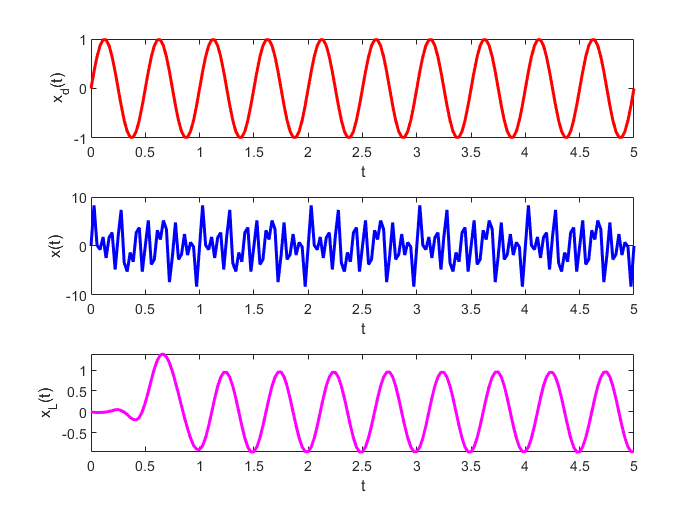

figure(2)
subplot(3,1,1);
plot(t,x1,'r-','linewidth',1.8);
xlabel('t'); ylabel('x_d(t)');
subplot(3,1,2);
plot(t,xn,'b-','linewidth',1.8);
xlabel('t'); ylabel('x(t)');
subplot(3,1,3);
plot(t,xL(1:length(t)),'m-','linewidth',1.8);
xlabel('t'); ylabel('x_L(t)');